# Example 1.3

% Jonghwan Lee, Jan 2021 - Jan 2023

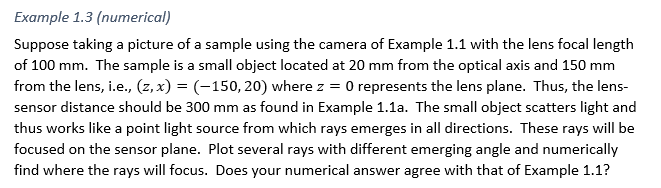

## Symbolic computation

Set the input ray vector and RTM.

Get the output ray vector.

clear

syms f z_samp x_samp positive  % constants given by the problem
syms theta_samp z positive  % parameter and key variable we set
assume(z_samp > f)

rIn = [x_samp theta_samp]'  % input ray vector

$$rIn = \left(\begin{array}{c} x_{\mathrm{samp}}\\ \theta_{\mathrm{samp}} \end{array}\right)$$


rtmSys = [1 z; 0 1] * [1 0; -1/f 1] * [1 z_samp; 0 1]  % RTM of whole system

$$rtmSys = \left(\begin{array}{cc} 1-\frac{z}{f} & z-z_{\mathrm{samp}}\,\left(\frac{z}{f}-1\right)\\ -\frac{1}{f} & 1-\frac{z_{\mathrm{samp}}}{f} \end{array}\right)$$


rOut = rtmSys * rIn  % output ray vector

$$rOut = \left(\begin{array}{c} \theta_{\mathrm{samp}}\,\left(z-z_{\mathrm{samp}}\,\left(\frac{z}{f}-1\right)\right)-x_{\mathrm{samp}}\,\left(\frac{z}{f}-1\right)\\ -\frac{x_{\mathrm{samp}}}{f}-\theta_{\mathrm{samp}}\,\left(\frac{z_{\mathrm{samp}}}{f}-1\right) \end{array}\right)$$

Set the position of the output ray as a function of the parameters.

xOut(z, theta_samp, f, z_samp, x_samp) = rOut(1)

$$xOut(z, theta\_samp, f, z\_samp, x\_samp) = \theta_{\mathrm{samp}}\,\left(z-z_{\mathrm{samp}}\,\left(\frac{z}{f}-1\right)\right)-x_{\mathrm{samp}}\,\left(\frac{z}{f}-1\right)$$


xOut(300, theta_samp, 100, 150, x_samp)  

$$ans = -2\,x_{\mathrm{samp}}$$

- This answer shows that the ray position does not depend on the initial ray angle `thSamp`. In other word, all the rays meet at the same point at `zImg = 300`.

More generally, find `zImg` at which all rays (only two rays here) with different initial angles meet.

xOut(z, theta_samp, 100, 150, x_samp)  

$$ans = -\theta_{\mathrm{samp}}\,\left(\frac{z}{2}-150\right)-x_{\mathrm{samp}}\,\left(\frac{z}{100}-1\right)$$


xOutDiff(z, f, z_samp, x_samp) = ...
    xOut(z, 0, f, z_samp, x_samp) - xOut(z, 0.1, f, z_samp, x_samp)

$$xOutDiff(z, f, z\_samp, x\_samp) = \frac{z_{\mathrm{samp}}\,\left(\frac{z}{f}-1\right)}{10}-\frac{z}{10}$$


zImg(f, z_samp, x_samp) = solve( xOutDiff == 0 , z)

$$zImg(f, z\_samp, x\_samp) = -\frac{f\,z_{\mathrm{samp}}}{f-z_{\mathrm{samp}}}$$


[zImg(f, z_samp, x_samp), solPara, solCond] = ...
    solve( xOutDiff == 0 , z, ReturnConditions=true);
solCond

$$solCond = f\,z_{\mathrm{samp}}\,\left(f-z_{\mathrm{samp}}\right)<0$$


zImg(100, 150, 20)

$$ans = 300$$

- Same as what we found from the thin lens equation in Example 1.1a.

## Numerical computation

Set the values given in the question.  All lengths are in [mm].

clear

f = 100;  % the lens focal length
xSamp = 20;  % the initial x position: the sample position
zSamp = -150;  % the initial z position: the sample position

Set a numerical array of z.

dz = 1;  % step size in z; arbitrarily chosen
zEnd = 400;  % the z position at which our calculation will stop
z = zSamp:dz:zEnd;  % array of z positions
nz = numel(z);  % length of the array
z

z =   -150  -149  -148  -147  -146  -145  -144  -143  -142  -141  -140  -139  -138  -137  -136  -135  -134  -133  -132  -131  -130  -129  -128  -127  -126  -125  -124  -123  -122  -121  -120  -119  -118  -117  -116  -115  -114  -113  -112  -111  -110  -109  -108  -107  -106  -105  -104  -103  -102  -101


Set RTMs

rtmLens = [1 0; -1/f 1]  % RTM of the lens

rtmLens =     1.0000         0
   -0.0100    1.0000


rtmAir = [1 dz; 0 1]  % RTM of a thin air slab with the thickness of dz

rtmAir =      1     1
     0     1


#### Build a code with a simple case for which you already know the answer: Trace a ray incident normal to the lens.

Set an empty `2 x nz` matrix for the ray vectors

thSamp = 0;  % the initial ray angle: a ray normal to the lens

r = zeros(2,nz);  % array of ray vectors (at every z position).  r(1,iz) is the height (x), and r(2,iz) is the angle at iz'th z position
r(:,1) = [xSamp thSamp]';  % the initial ray vector.  we need the transpose (') as r(:,1) is a column vector.
r

r =     20     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Get a ray vector at each z position, step by step from the initial position

for iz=2:nz
    r(:,iz) = rtmAir * r(:,iz-1);  % multiply the air RTM
    if z(iz) == 0  % multiply the lens RTM when z = 0 (the position of the lens)
        r(:,iz) = rtmLens * r(:,iz);
    end
end
r

r =     20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Plot the x positions of the found ray vectors as a function of z

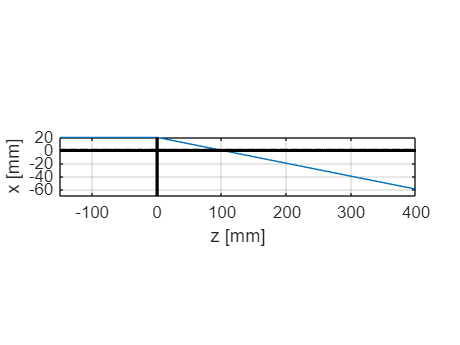

figure;
plot(z, r(1,:));  
line(z, zeros(size(z)), Color='k', LineWidth=2);  % optical axis
line([0 0], get(gca,'ylim'), Color='k', LineWidth=2);  % lens
axis image;  % set x and z scales identical
grid on;
xlabel('z [mm]');
ylabel('x [mm]');

#### Build a code for general cases: Trace 9 rays with different initial angles.

Set initial angles as an array

thSamp = linspace(-pi/8, pi/8, 9)

thSamp =    -0.3927   -0.2945   -0.1963   -0.0982         0    0.0982    0.1963    0.2945    0.3927


nthSamp = numel(thSamp)

nthSamp = 9

Repeat the above simple code of tracing a ray, for each of the initial angles

r = zeros(2,nz,nthSamp);  % a set of ray vectors for each z position and each initial angle
for ith=1:nthSamp  
    thSamp1 = thSamp(ith);  % ith-th angle value
    
    % a code block similar to the above
    r1 = zeros(2,nz);  % the 2 x nz matrix of ray vectors (at every z position) for the given angle
    r1(:,1) = [xSamp thSamp1]';
    for iz=2:nz
        r1(:,iz) = rtmAir * r1(:,iz-1);  % multiply the air RTM
        if z(iz) == 0  % multiply the lens RTM when z = 0 (the position of the lens)
            r1(:,iz) = rtmLens * r1(:,iz);
        end
    end
    
    % assign the calculated r1 to r
    r(:,:,ith) = r1;
end
r

r = r(:,:,1) =

   20.0000   19.6073   19.2146   18.8219   18.4292   18.0365   17.6438   17.2511   16.8584   16.4657   16.0730   15.6803   15.2876   14.8949   14.5022   14.1095   13.7168   13.3241   12.9314   12.5387   12.1460   11.7533   11.3606   10.9679   10.5752   10.1825    9.7898    9.3971    9.0044    8.6117    8.2190    7.8263    7.4336    7.0409    6.6482    6.2555    5.8628    5.4701    5.0774    4.6847    4.2920    3.8993    3.5066    3.1139    2.7212    2.3285    1.9358    1.5431    1.1504    0.7577    0.3650   -0.0277   -0.4204   -0.8131   -1.2058   -1.5984   -1.9911   -2.3838   -2.7765   -3.1692   -3.5619   -3.9546   -4.3473   -4.7400   -5.1327   -5.5254   -5.9181   -6.3108   -6.7035   -7.0962   -7.4889   -7.8816   -8.2743   -8.6670   -9.0597   -9.4524   -9.8451  -10.2378  -10.6305  -11.0232  -11.4159  -11.8086  -12.2013  -12.5940  -12.9867  -13.3794  -13.7721  -14.1648  -14.5575  -14.9502  -15.3429  -15.7356  -16.1283  -16.5210  -16.9137  -17.3064  -17.6991  -18.0918  -1

Plot the x positions of the nine rays over the z axis

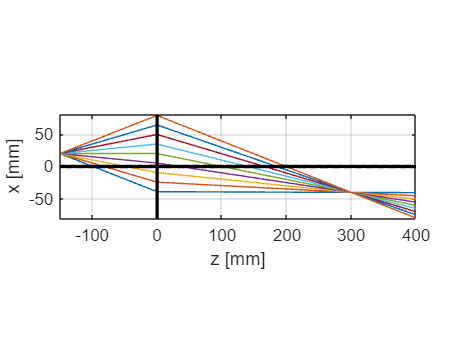

figure;
plot(z, squeeze(r(1,:,:)));  
line(z, zeros(size(z)), Color='k', LineWidth=2);  % optical axis
line([0 0], get(gca,'ylim'), Color='k', LineWidth=2);  % lens
axis image;  % set x and z scales identical
grid on;
xlabel('z [mm]');
ylabel('x [mm]');

#### Find the z position at which all rays meet (i.e., focused).  

Here, we will find it by searching where a variance in the x positions between rays is minimized.

First, find the index of the array `z` for the lens position.  We will investigate the variance only after this index (i.e., after the lens) because the initial position *before *the lens had zero variance.

iz0 = find(z==0)  % iz index of the lens (z=0).  

iz0 = 151

Set the variance of x and find the z index at which the variance is minimized.

varX = squeeze(var(r(1,:,:), [], 3))  % variance of x (1st element of the first dimension) along thSamp (the 3rd dimension)

varX = 1.0e+03 *

         0    0.0001    0.0003    0.0007    0.0012    0.0018    0.0026    0.0035    0.0046    0.0059    0.0072    0.0087    0.0104    0.0122    0.0142    0.0163    0.0185    0.0209    0.0234    0.0261    0.0289    0.0319    0.0350    0.0382    0.0416    0.0452    0.0489    0.0527    0.0567    0.0608    0.0651    0.0695    0.0740    0.0787    0.0836    0.0886    0.0937    0.0990    0.1044    0.1099    0.1157    0.1215    0.1275    0.1337    0.1399    0.1464    0.1530    0.1597    0.1665    0.1736


[varXmin, iz] = min(varX(iz0:end))  % find the min variance for iz >= iz0

varXmin = 2.8602e-25

iz = 301

iz = iz - 1 + iz0  % compensate for iz0

iz = 451

Find x at the focused position.

meanX = mean(squeeze(r(1,iz,:)))  % average x position of the traced rays

meanX = -40.0000

Print the result.

fprintf("The rays focus at [z x] = [%.2f %.2f] mm with x variance = %.3f. \n", ...
    z(iz), meanX, varXmin);

The rays focus at [z x] = [300.00 -40.00] mm with x variance = 0.000. 


fprintf("The magnification is %.2f. \n", abs(meanX/xSamp));

The magnification is 2.00. 
